Questions:

1) i) Open loop transfer function

Location of poles and Zeros

Pole-Zero Map

a=1;
b=8;
k=10.8E8;
j=10.8E8;
sys= tf([k k*a],[j j*b 0 0]) %OLTF

sys =
 
     1.08e09 s + 1.08e09
  -------------------------
  1.08e09 s^3 + 8.64e09 s^2
 
Continuous-time transfer function.



pole(sys)                    %Location of poles

ans =      0
     0
    -8


zero(sys)                    %Location of zeros

ans = -1

subplot(2,2,1)
pzmap(sys)                   %Pole zero map

1) ii) Timing Responses

s = tf('s');
sgtitle('Open Loop Characteristics') 
subplot(2,2,2)
impulse(sys)

subplot(2,2,3)
step(sys)

subplot(2,2,4)
title('Ramp Response')
step(sys/s)

2) Closed Loop Transfer function

sys_cl = feedback(sys,-1)

sys_cl =
 
                1.08e09 s + 1.08e09
  -----------------------------------------------
  1.08e09 s^3 + 8.64e09 s^2 - 1.08e09 s - 1.08e09
 
Continuous-time transfer function.



tf(sys_cl);     %CL Plot
% Root Locus and step response of closed loop function
figure
sgtitle('Closed Loop')
step(sys_cl)
 
figure
sgtitle('Closed Loop')
rlocus(sys_cl)

Question 2

Defining the transfer functions:

i)The constant gain function:

a=1;
b=8;
k=10.8E8;
j=10.8E8;
nk=[0,0,0,1];
dk=[0,0,0,1];

G(s) and Kg(s):

ng=[0 0 k k*a];
dg=[j j*b 0 0];
[nfp,dfp]=series1(nk,dk,ng,dg);

The net unity feedback system:

[nt,dt]=feedback1(nfp,dfp,[0,0,0,1],[0,0,0,1]);
T=tf(nt,dt);

Pole zero plot:

figure;
pzplot(T)

From the pole zero plot we can clearly see that the poles lie on the LHP => that the system is stable.

ii)Varying K (K=25)

nk=[0,0,0,25];
dk=[0,0,0,1];

[nfp,dfp]=series1(nk,dk,ng,dg);

[nt,dt]=feedback1(nfp,dfp,[0,0,0,25],[0,0,0,1]);
T=tf(nt,dt);

Pole zero plot:

figure;
pzplot(T)

 The poles lie exactly on top of the jW axis.

Hence the system is marginally stable. (k=2)

3) a)

Kp = 3 %Proportional Controller 

Kp = 3

K = 1;
H = 1;  % Unity Feedback
 
% Step response of open loop function
sys1 = sys*K*Kp;
figure
sgtitle('Open Loop, K=1')
step(sys1)
 
sys_cl1 = feedback(sys1*K,H)

sys_cl1 =
 
                3.24e09 s + 3.24e09
  -----------------------------------------------
  1.08e09 s^3 + 8.64e09 s^2 + 3.24e09 s + 3.24e09
 
Continuous-time transfer function.



 
% Step response of closed loop function
figure
sgtitle('Closed Loop, K=1')
step(sys_cl1)
 
K = 2;
H = 1;  % Unity Feedback
 
sys_cl2 = feedback(sys1*K,H)

sys_cl2 =
 
                6.48e09 s + 6.48e09
  -----------------------------------------------
  1.08e09 s^3 + 8.64e09 s^2 + 6.48e09 s + 6.48e09
 
Continuous-time transfer function.



 
% Step response of closed loop function
figure
sgtitle('Closed Loop, K=2')
step(sys_cl2)
 
 
K = 5;
H = 1;  % Unity Feedback
 
sys_cl5 = feedback(sys1*K,H)

sys_cl5 =
 
                1.62e10 s + 1.62e10
  -----------------------------------------------
  1.08e09 s^3 + 8.64e09 s^2 + 1.62e10 s + 1.62e10
 
Continuous-time transfer function.



 
% Step response of closed loop function
figure
sgtitle('Closed Loop, K=5')
step(sys_cl5)


3) b)

Kp = 7  %Proportional Controller 

Kp = 7

H = 1;  % Unity Feedback
 
% Step response of open loop function
sys1 = sys*Kp;
figure
sgtitle('Open Loop')
subplot(2,1,1)
step(sys1)
subplot(2,1,2)
rlocus(sys1)
 
sys_cl1 = feedback(sys1,H)

sys_cl1 =
 
                7.56e09 s + 7.56e09
  -----------------------------------------------
  1.08e09 s^3 + 8.64e09 s^2 + 7.56e09 s + 7.56e09
 
Continuous-time transfer function.



 
% Step response of closed loop function
figure
sgtitle('Closed Loop')
subplot(2,1,1)
step(sys_cl1)
subplot(2,1,2)
rlocus(sys_cl1)

4)

Kp = 7;
Td = 2; 
tpdNum = [Kp*Td Kp];
tpdDen = 1;
tpd = tf(tpdNum,tpdDen)

tpd =
 
  14 s + 7
 
Continuous-time transfer function.



 
K = 1;
z = 1;
sys_zNum = [K K*z];
sys_zDen = 1;
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  s + 1
 
Continuous-time transfer function.



sys_PDC11 = feedback(sys * tpd * sys_z,1)

sys_PDC11 =
 
  1.512e10 s^3 + 3.78e10 s^2 + 3.024e10 s + 7.56e09
  -------------------------------------------------
  1.62e10 s^3 + 4.644e10 s^2 + 3.024e10 s + 7.56e09
 
Continuous-time transfer function.



figure
sgtitle('K=1, z=1')
subplot(2,1,1)
step(sys_PDC11)
subplot(2,1,2)
rlocus(sys_PDC11)
 
K = 1;
z = 5;
sys_zNum = [K K*z];
sys_zDen = 1;
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  s + 5
 
Continuous-time transfer function.



sys_PDC15 = feedback(sys * tpd * sys_z,1)

sys_PDC15 =
 
  1.512e10 s^3 + 9.828e10 s^2 + 1.21e11 s + 3.78e10
  -------------------------------------------------
  1.62e10 s^3 + 1.069e11 s^2 + 1.21e11 s + 3.78e10
 
Continuous-time transfer function.



figure
sgtitle('K=1, z=5')
subplot(2,1,1)
step(sys_PDC15)
subplot(2,1,2)
rlocus(sys_PDC15)
 
K = 2;
z = 1;
sys_zNum = [K K*z];
sys_zDen = 1;
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  2 s + 2
 
Continuous-time transfer function.



sys_PDC21 = feedback(sys * tpd * sys_z,1)

sys_PDC21 =
 
  3.024e10 s^3 + 7.56e10 s^2 + 6.048e10 s + 1.512e10
  ---------------------------------------------------
  3.132e10 s^3 + 8.424e10 s^2 + 6.048e10 s + 1.512e10
 
Continuous-time transfer function.



figure
sgtitle('K=2, z=1')
subplot(2,1,1)
step(sys_PDC21)
subplot(2,1,2)
rlocus(sys_PDC21)
 
K = 2;
z = 5;
sys_zNum = [K K*z];
sys_zDen = 1;
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  2 s + 10
 
Continuous-time transfer function.



sys_PDC25 = feedback(sys * tpd * sys_z,1)

sys_PDC25 =
 
  3.024e10 s^3 + 1.966e11 s^2 + 2.419e11 s + 7.56e10
  --------------------------------------------------
  3.132e10 s^3 + 2.052e11 s^2 + 2.419e11 s + 7.56e10
 
Continuous-time transfer function.



figure
sgtitle('K=2, z=5')
subplot(2,1,1)
step(sys_PDC25)
subplot(2,1,2)
rlocus(sys_PDC25)
 
% Without zero
Kp = 7;
Td = 2;
tpdNum = [Kp*Td Kp];
tpdDen = 1;
tpd = tf(tpdNum,tpdDen)

tpd =
 
  14 s + 7
 
Continuous-time transfer function.



 
K = 1;
sys_PDC1 = feedback(sys * tpd * K,1)

sys_PDC1 =
 
         1.512e10 s^2 + 2.268e10 s + 7.56e09
  -------------------------------------------------
  1.08e09 s^3 + 2.376e10 s^2 + 2.268e10 s + 7.56e09
 
Continuous-time transfer function.



figure
sgtitle('K=1')
subplot(2,1,1)
step(sys_PDC1)
subplot(2,1,2)
rlocus(sys_PDC1)
 
K = 2;
sys_PDC2 = feedback(sys * tpd * K,1)

sys_PDC2 =
 
         3.024e10 s^2 + 4.536e10 s + 1.512e10
  --------------------------------------------------
  1.08e09 s^3 + 3.888e10 s^2 + 4.536e10 s + 1.512e10
 
Continuous-time transfer function.



figure
sgtitle('K=2')
subplot(2,1,1)
step(sys_PDC2)
subplot(2,1,2)
rlocus(sys_PDC2)

5) a)

5)a)

Kp = 7;
Ti = 2;
sys_piNum = [Kp*Ti Kp];
sys_piDen = [Ti 0];
sys_pi = tf(sys_piNum,sys_piDen)

sys_pi =
 
  14 s + 7
  --------
    2 s
 
Continuous-time transfer function.



K = 1;
z = 1;
sys_zNum = [K K*z];
sys_zDen = [1 0];
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



sys_piC11 = feedback(sys * sys_pi * sys_z,1)

sys_piC11 =
 
                1.512e10 s^3 + 3.78e10 s^2 + 3.024e10 s + 7.56e09
  ------------------------------------------------------------------------------
  2.16e09 s^5 + 1.728e10 s^4 + 1.512e10 s^3 + 3.78e10 s^2 + 3.024e10 s + 7.56e09
 
Continuous-time transfer function.



figure
sgtitle('K=1, z=1')
subplot(2,1,1)
step(sys_piC11)

subplot(2,1,2)
rlocus(sys_piC11)
% For different values of K and Z
 
Kp = 7;
Ti = 2;
sys_piNum = [Kp*Ti Kp];
sys_piDen = [Ti 0];
sys_pi = tf(sys_piNum,sys_piDen)

sys_pi =
 
  14 s + 7
  --------
    2 s
 
Continuous-time transfer function.



K = 1;
z = 5;
sys_zNum = [K K*z];
sys_zDen = [1 0];
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  s + 5
  -----
    s
 
Continuous-time transfer function.






sys_piC11 = feedback(sys * sys_pi * sys_z,1)

sys_piC11 =
 
                1.512e10 s^3 + 9.828e10 s^2 + 1.21e11 s + 3.78e10
  ------------------------------------------------------------------------------
  2.16e09 s^5 + 1.728e10 s^4 + 1.512e10 s^3 + 9.828e10 s^2 + 1.21e11 s + 3.78e10
 
Continuous-time transfer function.



figure
sgtitle('K=1, z=5')
subplot(2,1,1)
step(sys_piC11)
subplot(2,1,2)
rlocus(sys_piC11)
% When k = 2 and Z = 1
Kp = 7;
Ti = 2;
sys_piNum = [Kp*Ti Kp];
sys_piDen = [Ti 0];
sys_pi = tf(sys_piNum,sys_piDen)

sys_pi =
 
  14 s + 7
  --------
    2 s
 
Continuous-time transfer function.



K = 2;
z = 1;
sys_zNum = [K K*z];



sys_zDen = [1 0];
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  2 s + 2
  -------
     s
 
Continuous-time transfer function.



sys_piC11 = feedback(sys * sys_pi * sys_z,1)

sys_piC11 =
 
                3.024e10 s^3 + 7.56e10 s^2 + 6.048e10 s + 1.512e10
  -------------------------------------------------------------------------------
  2.16e09 s^5 + 1.728e10 s^4 + 3.024e10 s^3 + 7.56e10 s^2 + 6.048e10 s + 1.512e10
 
Continuous-time transfer function.



figure
sgtitle('K=2, z=1')
subplot(2,1,1)
step(sys_piC11)
subplot(2,1,2)
rlocus(sys_piC11)

**ONLY WITH K **

K = 1;
H = 1;  % Unity Feedback
sys_cl = feedback(sys/K,H);
Kp = 7;
Ti = 2;



sys_piNum = [Kp*Ti Kp];
sys_piDen = [Ti 0];
sys_pi = tf(sys_piNum,sys_piDen)

sys_pi =
 
  14 s + 7
  --------
    2 s
 
Continuous-time transfer function.



K = 1;
z = 1;
sys_piC11 = feedback(sys * sys_pi * K,1)

sys_piC11 =
 
                1.512e10 s^2 + 2.268e10 s + 7.56e09
  ----------------------------------------------------------------
  2.16e09 s^4 + 1.728e10 s^3 + 1.512e10 s^2 + 2.268e10 s + 7.56e09
 
Continuous-time transfer function.



figure
sgtitle('K=1, z=1')
subplot(2,1,1)
step(sys_piC11)
subplot(2,1,2)
rlocus(sys_piC11)

**When k = 3**

**Code :**

% Just with K 
sys_cl = feedback(sys/K,H);

Kp = 7;
Ti = 2;
sys_piNum = [Kp*Ti Kp];
sys_piDen = [Ti 0];
sys_pi = tf(sys_piNum,sys_piDen)

sys_pi =
 
  14 s + 7
  --------
    2 s
 
Continuous-time transfer function.



K = 3;
z = 1;
sys_piC11 = feedback(sys * sys_pi * K,1)

sys_piC11 =
 
                4.536e10 s^2 + 6.804e10 s + 2.268e10
  -----------------------------------------------------------------
  2.16e09 s^4 + 1.728e10 s^3 + 4.536e10 s^2 + 6.804e10 s + 2.268e10
 
Continuous-time transfer function.



figure
sgtitle('K=3, z=1')
subplot(2,1,1)
step(sys_piC11)
subplot(2,1,2)
rlocus(sys_piC11)
Kp = 7;
Ti = 2;
sys_piNum = [Kp*Ti Kp];
sys_piDen = [Ti 0];
sys_pi = tf(sys_piNum,sys_piDen)

sys_pi =
 
  14 s + 7
  --------
    2 s
 
Continuous-time transfer function.



K = 7;
z = 1;
sys_piC11 = feedback(sys * sys_pi * K,1)

sys_piC11 =
 
                1.058e11 s^2 + 1.588e11 s + 5.292e10
  -----------------------------------------------------------------
  2.16e09 s^4 + 1.728e10 s^3 + 1.058e11 s^2 + 1.588e11 s + 5.292e10
 
Continuous-time transfer function.



figure
sgtitle('K=7, z=1')
subplot(2,1,1)
step(sys_piC11)
subplot(2,1,2)
rlocus(sys_piC11)
%WITH 𝐾(S+Z)
Kp = 7;
Ti = 2;
sys_piNum = [Kp*Ti Kp];
sys_piDen = [Ti 0];
sys_pi = tf(sys_piNum,sys_piDen)

sys_pi =
 
  14 s + 7
  --------
    2 s
 
Continuous-time transfer function.



K = 1;
z = 1;
sys_zNum = [K K*z];
sys_zDen = 1;
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  s + 1
 
Continuous-time transfer function.



**iii)****𝐾****1+K2/s+K3S**

**Code:**

Kp = 7;
Ti = 2;
K1= 1;  %Define own values for K1, K2, K3
K2 = 2;
K3= 5;

sys_piNum = [Kp*Ti Kp];
sys_piDen = [Ti 0];
sys_pi = tf(sys_piNum,sys_piDen)

sys_pi =
 
  14 s + 7
  --------
    2 s
 
Continuous-time transfer function.



K = 1;
z = 1;
sys_zNum = [K3 K1 K2];
sys_zDen = [ 0 1 0];
sys_z = tf(sys_zNum, sys_zDen)

sys_z =
 
  5 s^2 + s + 2
  -------------
        s
 
Continuous-time transfer function.



sys_piC11 = feedback(sys * sys_pi * sys_z,1)

sys_piC11 =
 
         7.56e10 s^4 + 1.285e11 s^3 + 9.072e10 s^2 + 5.292e10 s + 1.512e10
  --------------------------------------------------------------------------------
  2.16e09 s^5 + 9.288e10 s^4 + 1.285e11 s^3 + 9.072e10 s^2 + 5.292e10 s + 1.512e10
 
Continuous-time transfer function.



figure
sgtitle('K=1, z=1')
subplot(2,1,1)
step(sys_piC11)
subplot(2,1,2)
rlocus(sys_piC11)


sys_piC11 = feedback(sys * sys_pi *sys_z ,1)

sys_piC11 =
 
         7.56e10 s^4 + 1.285e11 s^3 + 9.072e10 s^2 + 5.292e10 s + 1.512e10
  --------------------------------------------------------------------------------
  2.16e09 s^5 + 9.288e10 s^4 + 1.285e11 s^3 + 9.072e10 s^2 + 5.292e10 s + 1.512e10
 
Continuous-time transfer function.



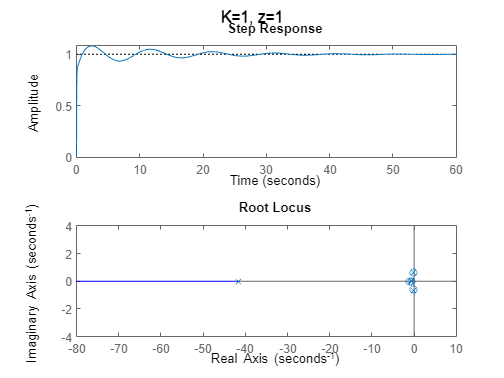

figure
sgtitle('K=1, z=1')
subplot(2,1,1)
step(sys_piC11)
subplot(2,1,2)
rlocus(sys_piC11)

5) b) Frequency Responses:

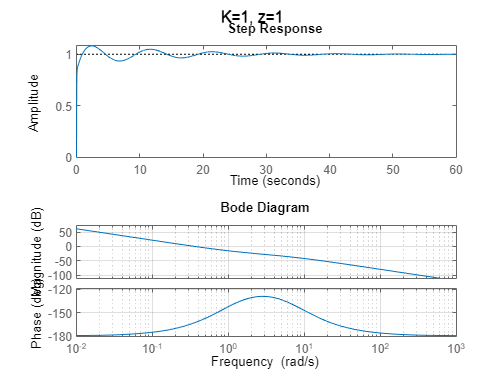

bode(sys)
grid 

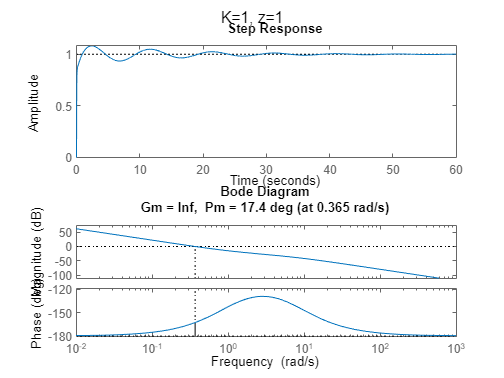


margin(sys)


nyquist(sys)
grid 

6) a) Phase Lag

%k=4;t=3;a=5 {reference}
K = 4;
t = 3;
a=5;
sys_Num = [K K*t*a];
sys_Den = [a*(a*t)];
sys_l = tf(sys_Num, sys_Den)

sys_l =
 
  4 s + 60
  --------
     75
 
Continuous-time transfer function.



sys_Plag = feedback(sys * sys_l,1)

sys_Plag =
 
         4.32e09 s^2 + 6.912e10 s + 6.48e10
  ------------------------------------------------
  8.1e10 s^3 + 6.523e11 s^2 + 6.912e10 s + 6.48e10
 
Continuous-time transfer function.



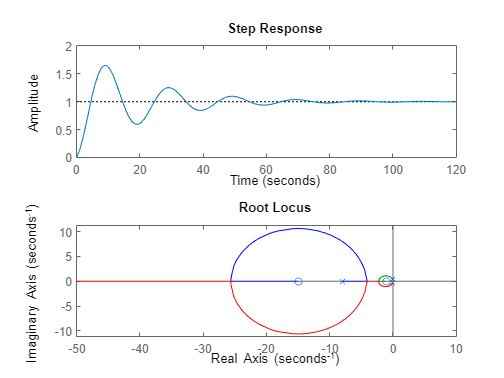



 
figure
subplot(2,1,1)
step(sys_Plag)
subplot(2,1,2)
rlocus(sys_Plag)

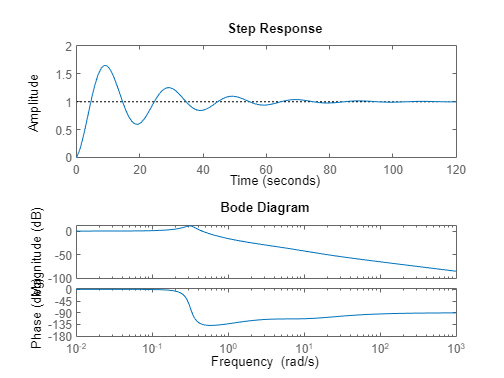

 
bode(sys_Plag)

nyquist(sys_Plag)
%k=4;t=5;a=6{greater than}
K = 4;
t = 5;

a=6

a = 6

sys_Num = [K K*t*a];
sys_Den = [a*(a*t)];
sys_l = tf(sys_Num, sys_Den)

sys_l =
 
  4 s + 120
  ---------
     180
 
Continuous-time transfer function.



sys_Plag = feedback(sys * sys_l,1)

sys_Plag =
 
         4.32e09 s^2 + 1.339e11 s + 1.296e11
  --------------------------------------------------
  1.944e11 s^3 + 1.56e12 s^2 + 1.339e11 s + 1.296e11
 
Continuous-time transfer function.



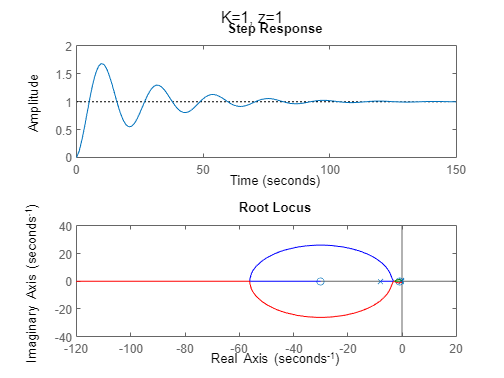


figure
subplot(2,1,1)
step(sys_Plag)
subplot(2,1,2)
rlocus(sys_Plag)

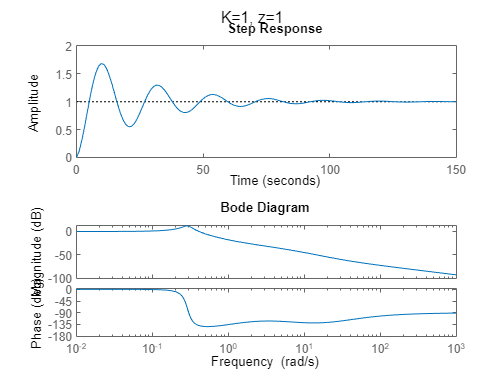

bode(sys_Plag)

nyquist(sys_Plag)
%k=4;t=2;a=0.5{lesser than}
K = 4;
t = 2;
a=0.5

a = 0.5000

sys_Num = [K K*t*a];
sys_Den = [a*(a*t)];
sys_l = tf(sys_Num, sys_Den)

sys_l =
 
  4 s + 4
  -------
    0.5
 
Continuous-time transfer function.



sys_Plag = feedback(sys * sys_l,1)

sys_Plag =
 
        4.32e09 s^2 + 8.64e09 s + 4.32e09
  ----------------------------------------------
  5.4e08 s^3 + 8.64e09 s^2 + 8.64e09 s + 4.32e09
 
Continuous-time transfer function.



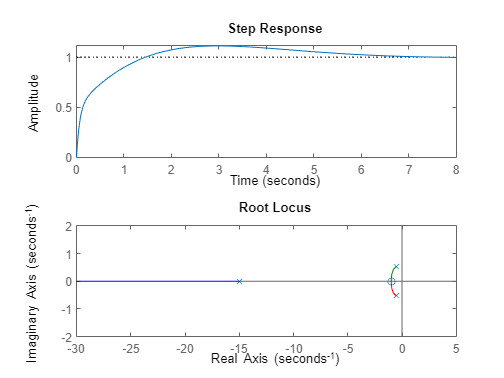


figure
subplot(2,1,1)
step(sys_Plag)
subplot(2,1,2)
rlocus(sys_Plag)

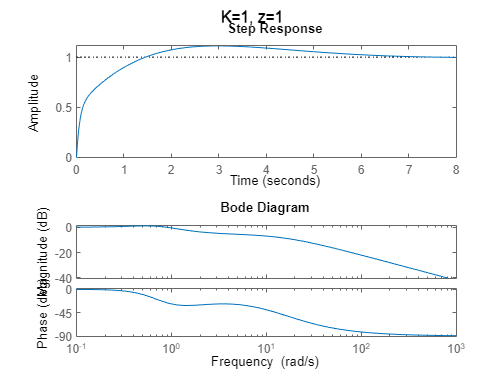


bode(sys_Plag)

nyquist(sys_Plag)

6) b) Phase Lead

%k=4;t=3;a=5 {reference}
K = 4;
t = 3;
a=5

a = 5

sys_Num = [K K*t*a];
sys_Den = [a*(a*t+1)];
sys_l = tf(sys_Num, sys_Den)

sys_l =
 
  4 s + 60
  --------
     80
 
Continuous-time transfer function.



sys_Plead = feedback(sys * sys_l,1)

sys_Plead =
 
         4.32e09 s^2 + 6.912e10 s + 6.48e10
  -------------------------------------------------
  8.64e10 s^3 + 6.955e11 s^2 + 6.912e10 s + 6.48e10
 
Continuous-time transfer function.



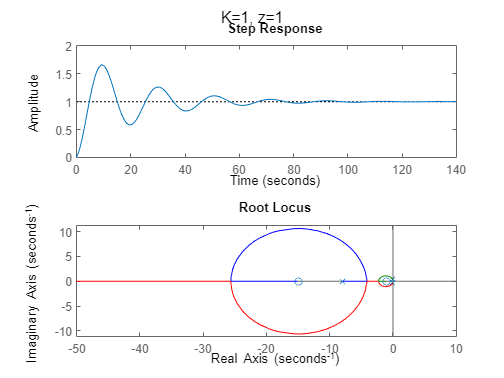


figure
subplot(2,1,1)
step(sys_Plead)
subplot(2,1,2)
rlocus(sys_Plead)

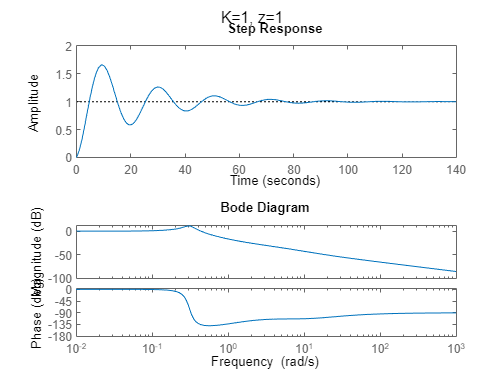


bode(sys_Plead)

nyquist(sys_Plead)
%k=4;t=5;a=6{greater than}
K = 4;
t = 5;
a=6

a = 6

sys_Num = [K K*t*a];
sys_Den = [a*(a*t)];
sys_l = tf(sys_Num, sys_Den)

sys_l =
 
  4 s + 120
  ---------
     180
 
Continuous-time transfer function.



sys_Plead = feedback(sys * sys_l,1)

sys_Plead =
 
         4.32e09 s^2 + 1.339e11 s + 1.296e11
  --------------------------------------------------
  1.944e11 s^3 + 1.56e12 s^2 + 1.339e11 s + 1.296e11
 
Continuous-time transfer function.



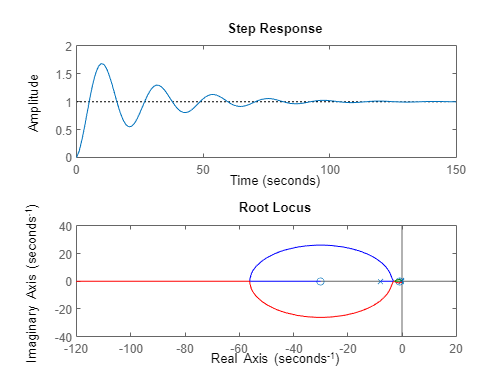


figure
subplot(2,1,1)
step(sys_Plead)
subplot(2,1,2)
rlocus(sys_Plead)

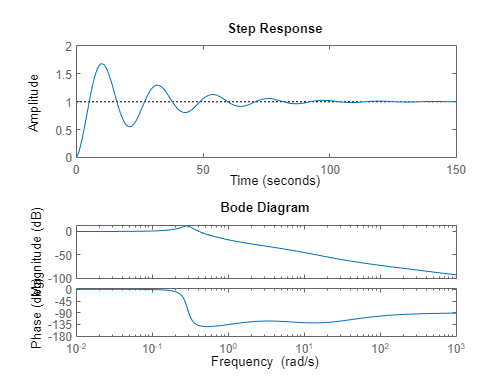


bode(sys_Plead)

nyquist(sys_Plead)
%k=4;t=2;a=0.5{lesser than}
close all;
K = 4;
t = 2;



a=0.5

a = 0.5000

sys_Num = [K K*t*a];
sys_Den = [a*(a*t)];
sys_l = tf(sys_Num, sys_Den)

sys_l =
 
  4 s + 4
  -------
    0.5
 
Continuous-time transfer function.



sys_Plead = feedback(sys * sys_l,1)

sys_Plead =
 
        4.32e09 s^2 + 8.64e09 s + 4.32e09
  ----------------------------------------------
  5.4e08 s^3 + 8.64e09 s^2 + 8.64e09 s + 4.32e09
 
Continuous-time transfer function.



 
figure
subplot(2,1,1)
step(sys_Plead)
subplot(2,1,2)
rlocus(sys_Plead)

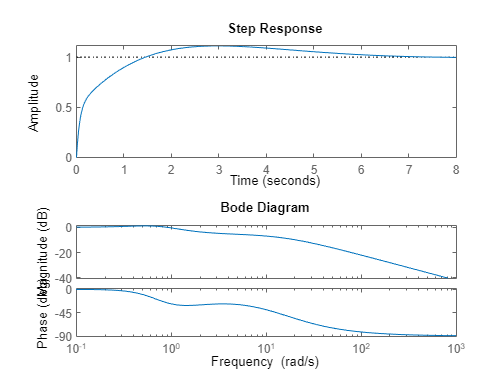

 
bode(sys_Plead)

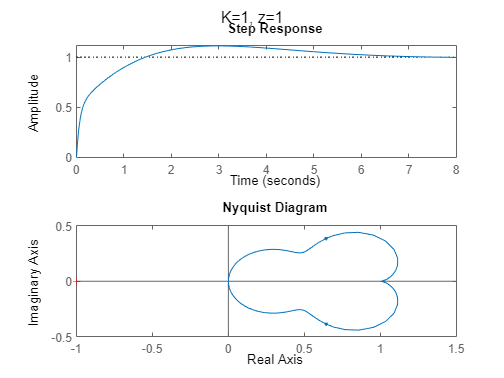

nyquist(sys_Plead)